Excercise B-17

load C:\class\coursefiles\mlbe\exercises\waistmeasure.mat

waist99 = waist(:,1);

waist99 =    64.7000
   99.9000
   81.6000
   90.7000
   64.1000
   64.6000
  108.0000
   76.5000
   74.4000
   81.0000


waist09 =    70.6000
   84.8000
  153.6000
   81.4000
   75.1000
  102.0000
   82.0000
   60.9000
   97.8000
  106.0000


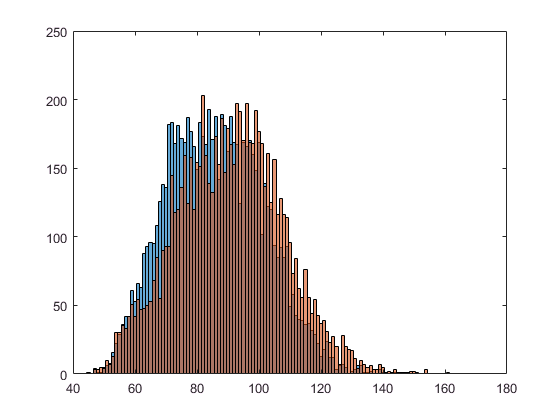

waist09 = waist(:,2);


sorted09 = sort(waist09);

sorted09 =    45.3000
   47.3000
   47.3000
   47.3000
   48.0000
   48.0000
   48.1000
   48.6000
   48.6000
   49.0000


sorted99 = sort(waist99);

sorted99 =    46.7000
   46.7000
   47.0000
   47.1000
   48.2000
   48.6000
   49.8000
   50.0000
   50.2000
   50.2000



[N99,edges99,bin99]= histcounts(waist99 ,'BinMethod', 'integers');

N99 =      4     1     1     5     6     8    16    22    29    36    42    42    61    53    66    63    88    93    96    95   108   126   138   136   182   183   168   181   172   169   187   177   166   149   183   173   167   193   171   188   142   189   181   162   188   169   167   124   169   166


edges99 =    46.5000   47.5000   48.5000   49.5000   50.5000   51.5000   52.5000   53.5000   54.5000   55.5000   56.5000   57.5000   58.5000   59.5000   60.5000   61.5000   62.5000   63.5000   64.5000   65.5000   66.5000   67.5000   68.5000   69.5000   70.5000   71.5000   72.5000   73.5000   74.5000   75.5000   76.5000   77.5000   78.5000   79.5000   80.5000   81.5000   82.5000   83.5000   84.5000   85.5000   86.5000   87.5000   88.5000   89.5000   90.5000   91.5000   92.5000   93.5000   94.5000   95.5000


bin99 =     19
    54
    36
    45
    18
    19
    62
    31
    28
    35


[N09,edges09,bin09]= histcounts(waist09 ,'BinMethod', 'integers');

N09 =      1     0     3     3     5     4    10     7    13    30    30    35    33    42    51    42    54    47    48    50    53    68    85    55    90    93    93   145   118   120   136   159   124   158   120   154   151   203   159   139   132   173   153   186   147   179   167   153   197   191


edges09 =    44.5000   45.5000   46.5000   47.5000   48.5000   49.5000   50.5000   51.5000   52.5000   53.5000   54.5000   55.5000   56.5000   57.5000   58.5000   59.5000   60.5000   61.5000   62.5000   63.5000   64.5000   65.5000   66.5000   67.5000   68.5000   69.5000   70.5000   71.5000   72.5000   73.5000   74.5000   75.5000   76.5000   77.5000   78.5000   79.5000   80.5000   81.5000   82.5000   83.5000   84.5000   85.5000   86.5000   87.5000   88.5000   89.5000   90.5000   91.5000   92.5000   93.5000


bin09 =     27
    41
   110
    37
    31
    58
    38
    17
    54
    62


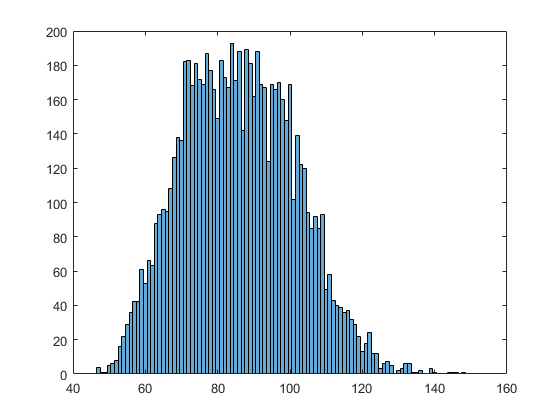


% 1999
histogram('BinEdges',edges99,'BinCounts',N99)
hold off

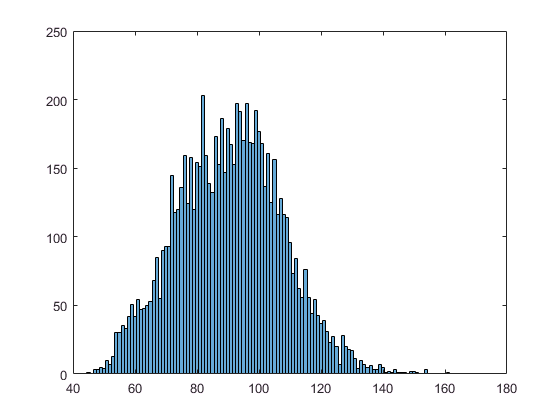

% 2009
histogram('BinEdges',edges09,'BinCounts',N09)


u99 = mean(waist99);

u99 = 85.9192

u09 = mean(waist09);

u09 = 90.4684


sd99 = std(waist99);

sd99 = 15.5576

sd09 = std(waist09);

sd09 = 16.9444

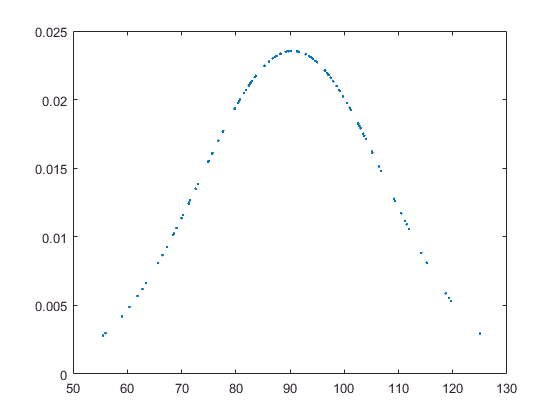


operand1 = (1/sqrt(2*pi));
w09 = (waist09(40:1:160));
w99 = (waist99(40:1:160));

top99 = ((w99 - u99).^2) / (2*(sd99).^2);
exp99 = exp(-top99);

top09 = ((w09 - u09).^2) / (2*(sd09).^2);
exp09 = exp(-top09);

Pw99 = operand1 * (exp99 / sd99);
Pw09 = operand1 * (exp09 / sd09);


plot(w09,Pw09,'.')

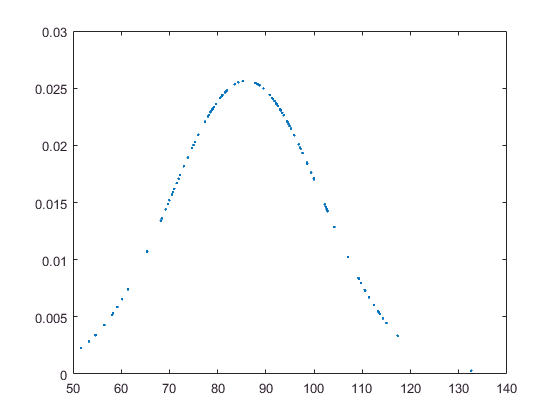

plot(w99,Pw99,'.')

## Mats solution

histogram(waist99,'BinMethod','integer')
hold on
histogram(waist09,'BinMethod','integer')
hold off

mu = mean(waist)
sigma = std(waist)

W = (40:160)';

D = (1/sqrt(2*pi))./sigma

P = exp(- (W - mu).^2 ./ (2*sigma.^2)) .*D

plot(W,P)
xlabel('waist size')
ylabel('fraction of people')
legend('1999','2009')

